# Problem 1

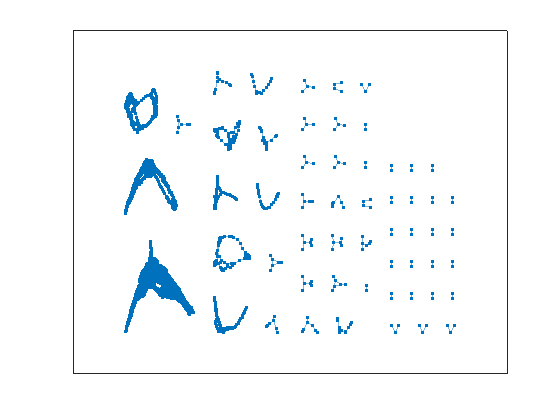

% Loading Data

data = load("usroads.mat");

G = graph(data.Problem.A);
plot(G)

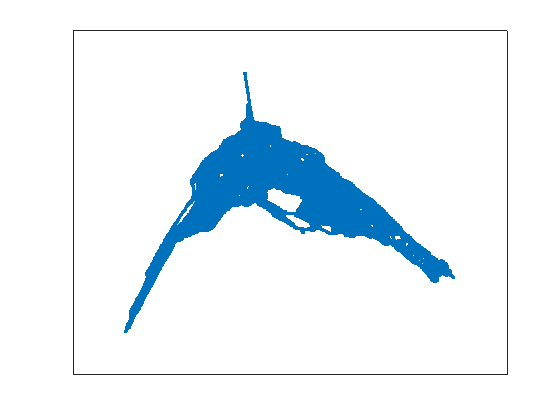

comps = conncomp(G);

SG = subgraph(G, comps==28);
plot(SG)

## Problem 1.1

A_SG = adjacency(SG);

A_SG2 = [0 0 0 0 0 0 0 0 1 0 0 0 0 0 0;
0 0 0 0 0 1 1 0 1 0 0 0 0 0 0;
0 0 0 0 1 0 0 0 1 0 0 0 0 0 0;
0 0 0 0 0 0 1 0 0 0 1 0 0 1 0;
0 0 1 0 0 0 0 0 0 0 1 0 0 1 0;
0 1 0 0 0 0 0 0 0 0 0 0 0 0 0;
0 1 0 1 0 0 0 1 0 0 0 0 0 0 1;
0 0 0 0 0 0 1 0 0 0 0 0 0 0 0;
1 1 1 0 0 0 0 0 0 0 0 1 1 0 1;
0 0 0 0 0 0 0 0 0 0 0 0 1 0 0;
0 0 0 1 1 0 0 0 0 0 0 0 0 1 0;
0 0 0 0 0 0 0 0 1 0 0 0 0 1 1;
0 0 0 0 0 0 0 0 1 1 0 0 0 0 0;
0 0 0 1 1 0 0 0 0 0 1 1 0 0 0;
0 0 0 0 0 0 1 0 1 0 0 1 0 0 0]

A_SG2 =      0     0     0     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     1     1     0     1     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     1     0     0     1     0
     0     0     1     0     0     0     0     0     0     0     1     0     0     1     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     1     0     0     0     1     0     0     0     0     0     0     1
     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0
     1     1     1     0     0     0     0     0     0     0     0     1     1     0     1
     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0



A_SG = A_SG./sum(A_SG)

A_SG =                  (17,1)                      1.0000
                 (17,2)                      1.0000
                  (7,3)                      1.0000
                 (62,4)                      1.0000
                 (52,5)                      1.0000
                 (83,6)                      1.0000
                  (3,7)                      0.5000
                 (47,7)                      0.5000
                 (56,8)                      1.0000
                (286,9)                      1.0000
                 (57,10)                     1.0000
                (127,11)                     1.0000
                (188,12)                     1.0000
                (282,13)                     1.0000
                (260,14)                     1.0000
                (243,15)                     1.0000
                (187,16)                     1.0000
                  (1,17)                     0.3333
                  (2,17)                     0.3333
     

## Problem 1.2

% Find the page rank of this network using power iteration.

% Need to find the page rank iteratively since the complete matrix is
% large...
alpha = 0.9;
k = 5;
n = length(A_SG);
%Make a column vector of 1's normalized to n
v = eye(n, 1) / n;

partial = alpha*A_SG*v;

v_sum = v + partial;

for i = 2:k
    partial = alpha*A_SG*partial;
    v_sum = v_sum + partial;
end

x = (1- alpha)*v_sum;
x

x = 1.0e-05 *

    0.1142
    0.0349
         0
    0.0006
         0
         0
         0
         0
         0
         0


sum(x*k)

ans = 1.8572e-05

%pr = ((1-alpha)/n)*pinv(eye(n,n) - alpha*A_SG)*eye(n,1)

### Sensitivity

%todo: Ask professor about sensitivity

k = 5;
n = length(A_SG);

tests = 10;
ranks = zeros(n, tests);
pos = 1;
for alpha = linspace(0.5,0.99,tests)

    %Make a column vector of 1's normalized to n
    v = eye(n, 1) / n;

    partial = alpha*A_SG*v;
    
    v_sum = v + partial;
    
    for i = 2:k
        partial = alpha*A_SG*partial;
        v_sum = v_sum + partial;
    end
    
    x = (1- alpha)*v_sum;
    ranks(:,pos) = x;
    pos = pos + 1;
end


### Plot Sensitivity

errors = zeros(tests,1);

errors =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


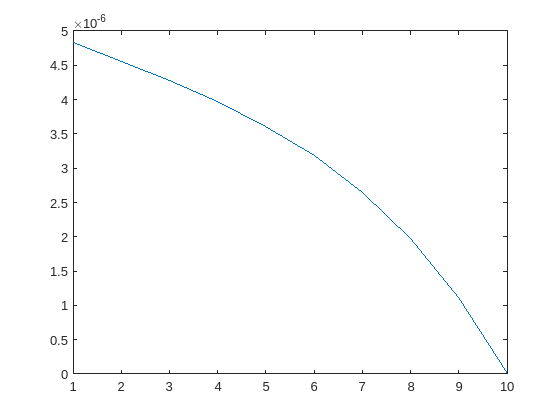


for i = 1:tests
    errors(i) = norm(ranks(:,i) - ranks(:,tests));
end

plot(errors)

## G49.mat

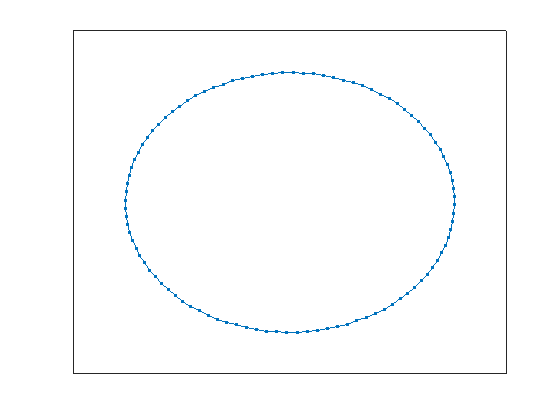

load('G49.mat')

A_G49 = graph(Problem.A);
plot(A_G49)

L = laplacian(A_G49);%A_G49*transpose(A_G49)
[D, S] = eigs(L, 3000);

s = diag(S);
%Find the minimum of S that isn't ~zero
[M, I] = min(s(abs(s) > 1e-15));

Cut = D(:,I) > 0;
plot(A_G49(Cut))

Error using indexing
Indexing not supported.